# Activdad 3.2 Simulación de trayectoria

## **Autores:**

Diego Garcia Rueda

Jonathan Josafat Vazquez Suarez

Jhonatan Yael Martinez Vargas 

## **Objetivo:**

Dadas los puntos que definen la trayectoria del robot y usando los principios de cinematica para un robot tipo movil de tipo diferencial visualizar la el reccorrido que hace el robot para recorrer todos los puntos.

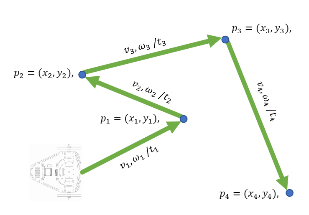

%Limpieza de pantalla
clear all
close all
clc

## Paso 01:  Definir configuraciones iniciales de la sumulación y del robot.

Al igual que en la simulación del cuadrado, para calcular ***tf*** se estan considerando velocidad lineal y angular de un 1 m/s, por lo que por cada metro de trayectoria que tenga la figur, se deben de ejecutar alguno de los sigueintes dos moviemientos (orientarse y avanzar), de esta maenra se establece que el tiempo de simulación es de 9.5 segundos

%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf = 9.5;            % Tiempo de simulación en segundos (s)
ts = 0.1;          % Tiempo de muestreo en segundos (s)
t = 0:ts:tf;       % Vector de tiempo
N = length(t);     % Muestras

%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Inicializamos las variables que se van a emplear
x1 = zeros (1, N+1);       % Posición (X) en el centro del eje que une las ruedas en metros (m)
y1 = zeros (1, N+1);       % Posición (Y) en el centro del eje que une las ruedas en metros (m)
phi = zeros (1, N+1);      % Orientación del robot en radiaanes (rad)

%Damos valores a nuestro punto inicial de posición y orientación
x1(1)=0;    %Posición inicial eje x
y1(1)=0;    %Posición inicial eje y
phi(1)=0;   %Orientación inicial del robot 

%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Inicializamos el punto de control 
hx= zeros (1, N+1);       % Posición en el eje (X) del punto de control en metros (m)
hy= zeros (1, N+1);       % Posición en el eje (Y) del punto de control en metros (m)

%Igualamos el punto de control con las proyecciones X1 y Y1 por su
%coincidencia
hx(1) = x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1) = y1(1);       % Posición del punto de control en el eje (Y) metros (m)

## Paso 02:  Definir los movienentos que debe hacer el robot para seguir la trayectoria.

Para poder seguir la trayectoria que se presenta en la imagen es importante planificar los movimiento a realizar, quedanos un set de instrucciones de la siguiente manera:

**Tramo 1 (v=0 m/s, w=pi/6 rad/s)**

**Tramo 2 (v=1 m/s, w=0 rad/s)**

**Tramo 3 (v=0 m/s, w=2/3pi rad/s)**

**Tramo 4 (v=1 m/s, w=0 rad/s)**

**Tramo 5 (v=0 m/s, w=-2/3pi rad/s)**

**Tramo 6 (v=1 m/s, w=0 rad/s)**

**Tramo 7 (v=1 m/s, w=0 rad/s)**

**Tramo 8 (v=0 m/s, w=pi/2 rad/s)**

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

v = [0*ones(1,10)    1*ones(1,10) 0*ones(1,10)      1*ones(1,10)  0*ones(1,10)      1*ones(1,15) 0*ones(1,10)     1*ones(1,21)]; % Velocidad lineal de referencia (m/s)
w = [pi/6*ones(1,10) 0*ones(1,10) 2/3*pi*ones(1,10) 0*ones(1,10) -2/3*pi*ones(1,10) 0*ones(1,15) -pi/2*ones(1,10) 0*ones(1,21)]; % Velocidad angular de referencia (rad/s)


## Paso 03: Simular la trayectoria del robot.

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k = 1:N 
    
    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1) = phi(k) + w(k) * ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k) * cos(phi(k)); % Posición en x 
    yp1=v(k) * sin(phi(k)); % Posición en y
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1) = x1(k) + ts * xp1; % Integral numérica (método de Euler)
    y1(k+1) = y1(k) + ts * yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1) = x1(k+1); 
    hy(k+1) = y1(k+1);

end

## Paso 04: Ejecutar el ambiente virtual para la simulacion.

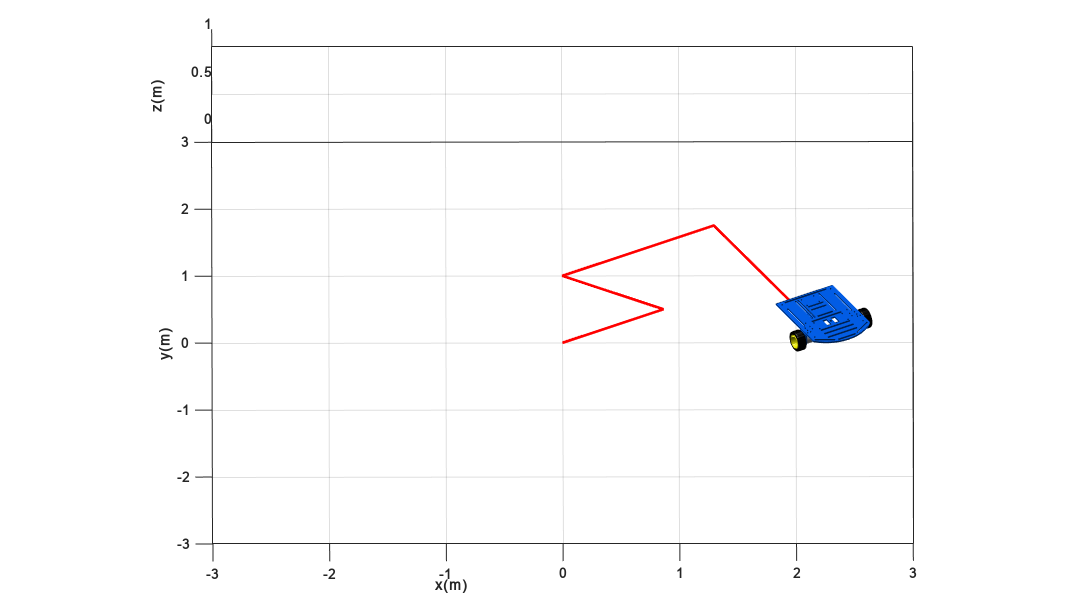

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 35]); % Orientacion de la figura
axis([-3 3 -3 3 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot;
H1=MobilePlot(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end